# Wave propagation through air and thin lens

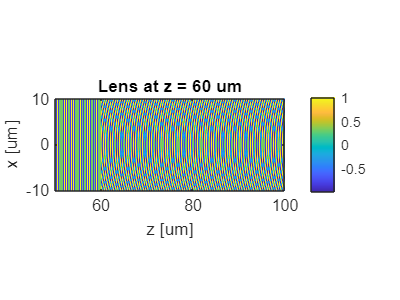

% Constants
E0 = 1.0;
lam = 500e-9;  % wavelength in meters
f = 40e-6;     % focal length in meters
k = 2*pi/lam;  % wave number

% Discretization parameters
dz = 0.1e-6;  % step size in z-direction
z = 50e-6:dz:100e-6;
x = -10e-6:dz:10e-6;
y = -10e-6:dz:10e-6;

% Generate 2D grid for x and y
[gx, gy] = ndgrid(x, y);

% Initialize E field
nx = length(x);
ny = length(y);
nz = length(z);
E = complex(zeros(nx, ny, nz));
E(:,:,1) = E0 * exp(1i*k*z(1));

% Compute E field slab by slab
for iz = 2:nz
    % Propagation through air
    E(:,:,iz) = E(:,:,iz-1) .* exp(1i * k * dz);
    
    % Check if current slab is at lens position
    if z(iz) == 60e-6
        % Propagation through lens
        E(:,:,iz) = E(:,:,iz) .* exp(-1i * k/2/f .* (gx.^2 + gy.^2));
    end
end

% Visualize E field at y = 0
iy0 = find(y == 0);
visualizeEField(z, x, E, iy0);

- Something is wrong!

function visualizeEField(z, x, E, iy0)
    figure;
    imagesc(z*1e6, x*1e6, real(squeeze(E(:,iy0,:))));
    set(gca, 'YDir', 'normal');
    axis image;
    colorbar;
    xlabel('z [um]');
    ylabel('x [um]');
    title('Lens at z = 60 um');
end